Ebad Syed

1270329

# EENG 860 Special Topics: Digital Image Processing Project 1

## **Guassian FIlter**

ImageOriginal = imread("lena_gray_512.tif"); %load original image


%selecting standard deviation value
%we are selecting the value of standard deviation as 1,3 and 5
sigmaValues = [1 3 5];

%Defining the size of filter
%size of the filter must be odd for MATLAB function to work 
%Filter size of 6sigma*6sigma
filterSize = [(6*sigmaValues(1))-1 (6*sigmaValues(1))-1;(6*sigmaValues(2))-1 (6*sigmaValues(2))-1;(6*sigmaValues(3))-1 (6*sigmaValues(3))-1];

%Applying the Guassian filter using defined sigma values and filter size
ImageOut1 = imgaussfilt(ImageOriginal,sigmaValues(1),'FilterSize',filterSize(1,:));
ImageOut2 = imgaussfilt(ImageOriginal,sigmaValues(2),'FilterSize',filterSize(2,:));
ImageOut3 = imgaussfilt(ImageOriginal,sigmaValues(3),'FilterSize',filterSize(3,:));



### Image Display

We can observe increasing the number of sigma keep increasing the blur. We can see that using the Sigma of value 1 most of the noise is already removed. When we increase sigma to 3 almost all the noise is removed but image also starts losing its feature. For value of 5 it looks very different from original image and much information is lost at expense of smoothing. 

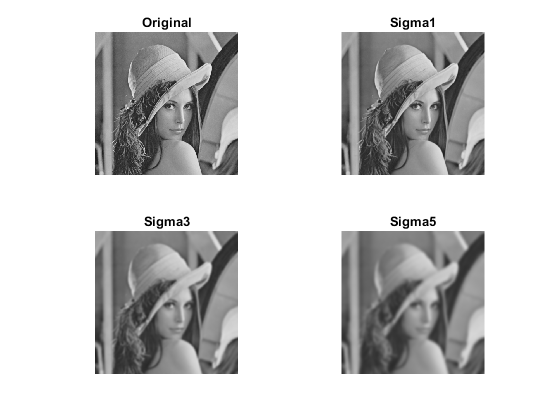

figure;
subplot(2,2,1),imshow(ImageOriginal),title('Original') %image display in a single figure
subplot(2,2,2),imshow(ImageOut1),title(['Sigma',num2str(sigmaValues(1))])  
subplot(2,2,3),imshow(ImageOut2), title(['Sigma',num2str(sigmaValues(2))])
subplot(2,2,4),imshow(ImageOut3), title(['Sigma',num2str(sigmaValues(3))])

### Patch Analysis

Selecting a patch allows us to closely look at the image and compare the effect of Guassian Filter. The patch analysis shows that by using value of Sigma 1 we already have achieved smoothness and removed noise.

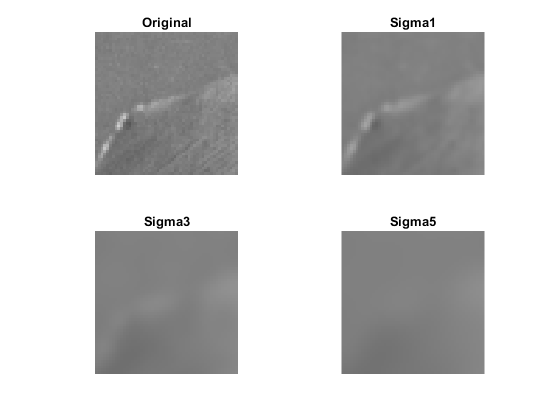

patchOriginal = imcrop(ImageOriginal,[150, 35, 50 50]); %selection of patch
patchOut1 = imcrop(ImageOut1,[150, 35, 50 50]);
patchOut2 = imcrop(ImageOut2,[150, 35, 50 50]);
patchOut3 = imcrop(ImageOut3,[150, 35, 50 50]);

figure;
subplot(2,2,1),imshow(patchOriginal),title('Original')  
subplot(2,2,2),imshow(patchOut1),title(['Sigma',num2str(sigmaValues(1))])  
subplot(2,2,3),imshow(patchOut2), title(['Sigma',num2str(sigmaValues(2))])
subplot(2,2,4),imshow(patchOut3), title(['Sigma',num2str(sigmaValues(3))])

### Histogram Analysis

Histogram Analysis shows that increasing the Standard Deviation, reduces the bins at high and low level intensities.

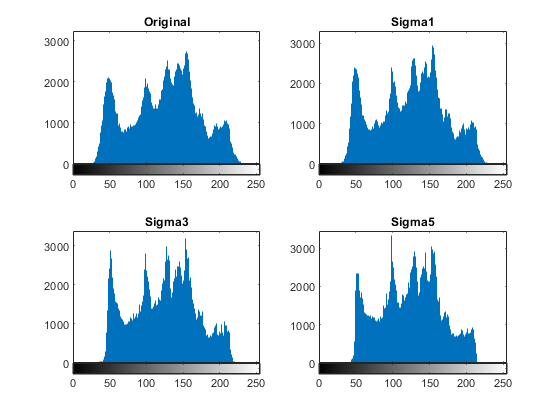

figure;
subplot(2,2,1),imhist(ImageOriginal),title('Original')  %histogram display
subplot(2,2,2),imhist(ImageOut1),title(['Sigma',num2str(sigmaValues(1))])  
subplot(2,2,3),imhist(ImageOut2), title(['Sigma',num2str(sigmaValues(2))])
subplot(2,2,4),imhist(ImageOut3), title(['Sigma',num2str(sigmaValues(3))])

## Bilateral Filter

For Bilateral filtering we first compute variance of a patch, which approximates the variance of the noise.

patch = imcrop(ImageOriginal,[150, 35, 50 50]); %select patch
patchVar = std2(patch)^2; %variance of the patch


Selecting 3 Degree of Smoothing, which are: 

1)Half variance of noise

2)Equal to variance of noise

3)Twice the variance of noise

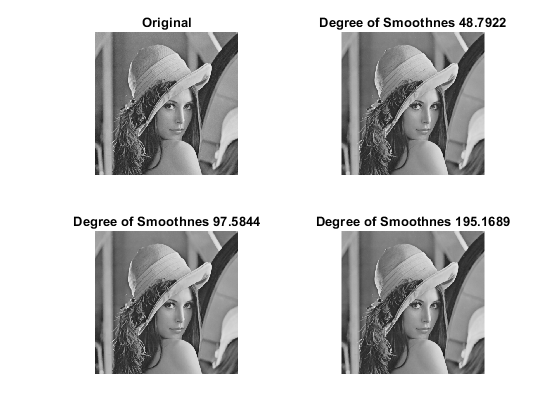

%degree of smoothing

DoS1 = 0.5*patchVar;
DoS2 = 1*patchVar;
DoS3 = 2*patchVar;

%not specifying spatial sigma
ImageOut1 = imbilatfilt(ImageOriginal,DoS1);
ImageOut2 = imbilatfilt(ImageOriginal,DoS2);
ImageOut3 = imbilatfilt(ImageOriginal,DoS3);

figure;
subplot(2,2,1),imshow(ImageOriginal),title('Original') %image display in a single figure
subplot(2,2,2),imshow(ImageOut1),title(['Degree of Smoothnes ',num2str(DoS1)])  
subplot(2,2,3),imshow(ImageOut2), title(['Degree of Smoothnes ',num2str(DoS2)])
subplot(2,2,4),imshow(ImageOut3), title(['Degree of Smoothnes ',num2str(DoS3)])

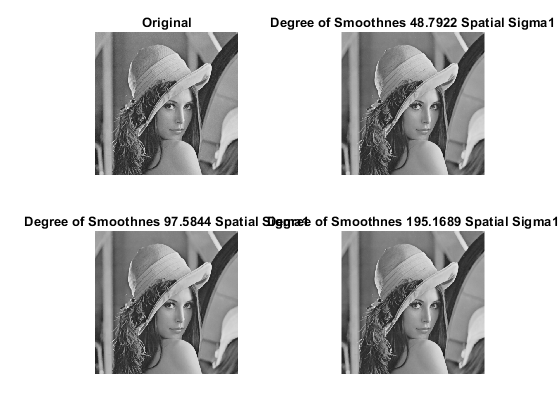

%Spatial Sigma as 1
ImageOut1 = imbilatfilt(ImageOriginal,DoS1,sigmaValues(1));
ImageOut2 = imbilatfilt(ImageOriginal,DoS2,sigmaValues(1));
ImageOut3 = imbilatfilt(ImageOriginal,DoS3,sigmaValues(1));

figure;
subplot(2,2,1),imshow(ImageOriginal),title('Original') %image display in a single figure
subplot(2,2,2),imshow(ImageOut1),title(['Degree of Smoothnes ',num2str(DoS1),' Spatial Sigma',num2str(sigmaValues(1))])  
subplot(2,2,3),imshow(ImageOut2), title(['Degree of Smoothnes ',num2str(DoS2),' Spatial Sigma',num2str(sigmaValues(1))])
subplot(2,2,4),imshow(ImageOut3), title(['Degree of Smoothnes ',num2str(DoS3),' Spatial Sigma',num2str(sigmaValues(1))])

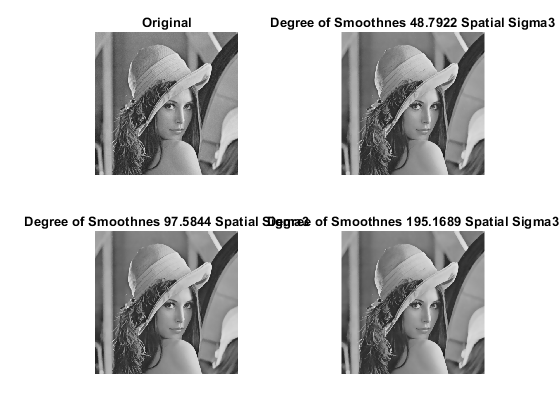

%Spatial Sigma as 3
ImageOut1 = imbilatfilt(ImageOriginal,DoS1,sigmaValues(2));
ImageOut2 = imbilatfilt(ImageOriginal,DoS2,sigmaValues(2));
ImageOut3 = imbilatfilt(ImageOriginal,DoS3,sigmaValues(2));

figure;
subplot(2,2,1),imshow(ImageOriginal),title('Original') %image display in a single figure
subplot(2,2,2),imshow(ImageOut1),title(['Degree of Smoothnes ',num2str(DoS1),' Spatial Sigma',num2str(sigmaValues(2))])  
subplot(2,2,3),imshow(ImageOut2), title(['Degree of Smoothnes ',num2str(DoS2),' Spatial Sigma',num2str(sigmaValues(2))])
subplot(2,2,4),imshow(ImageOut3), title(['Degree of Smoothnes ',num2str(DoS3),' Spatial Sigma',num2str(sigmaValues(2))])

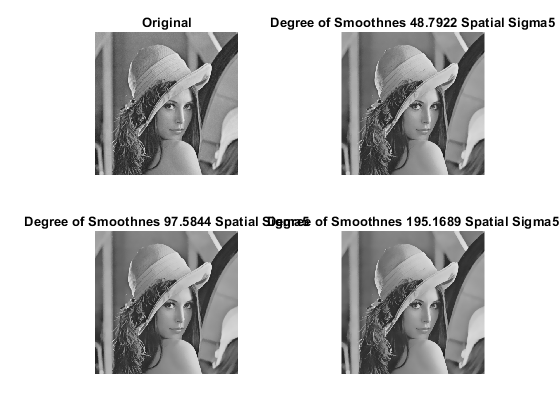



%Spatial Sigma as 5
ImageOut1 = imbilatfilt(ImageOriginal,DoS1,sigmaValues(3));
ImageOut2 = imbilatfilt(ImageOriginal,DoS2,sigmaValues(3));
ImageOut3 = imbilatfilt(ImageOriginal,DoS3,sigmaValues(3));

figure;
subplot(2,2,1),imshow(ImageOriginal),title('Original') %image display in a single figure
subplot(2,2,2),imshow(ImageOut1),title(['Degree of Smoothnes ',num2str(DoS1),' Spatial Sigma',num2str(sigmaValues(3))])  
subplot(2,2,3),imshow(ImageOut2), title(['Degree of Smoothnes ',num2str(DoS2),' Spatial Sigma',num2str(sigmaValues(3))])
subplot(2,2,4),imshow(ImageOut3), title(['Degree of Smoothnes ',num2str(DoS3),' Spatial Sigma',num2str(sigmaValues(3))])

## Conclusion

We can observer that Bilateral Filtering produces more pleasant results than Guassian Filtering. 

Moreover, Bilateral and Guassian filter both removes noise in uniform spaces. However, Bilateral doesn't introduce blur between objects. Thus the edges are still prominent in Bilateral Filtering despite increasing the value of Sigma. In Guassian filter we also saw that increasing the value of spatial sigma reduces the details in the images.